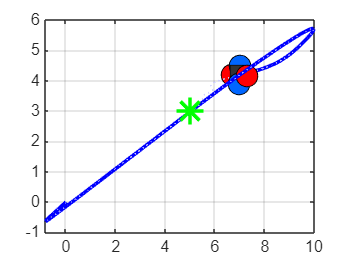

%% Extract data
x = out.x_log.Data;
y = out.y_log.Data;
z = out.z_log.Data;
t = out.x_log.Time;

try
    phi   = out.phi_log.Data;
    theta = out.theta_log.Data;
    psi   = out.psi_log.Data;
catch
    phi   = zeros(size(x));
    theta = zeros(size(x));
    psi   = zeros(size(x));
end

%% Downsample
n_frames = 150;
idx   = round(linspace(1, length(x), n_frames));
x=x(idx); y=y(idx); z=z(idx); t=t(idx);
phi=phi(idx); theta=theta(idx); psi=psi(idx);

%% Setup
arm_len = 0.3;
xL=[min(x)-2 max(x)+2];
yL=[min(y)-2 max(y)+2];
zL=[0 max(z)+2];

fig = figure('Color','white','Position',[100 100 800 600]);

%% Record frames
frames(n_frames) = struct('cdata',[],'colormap',[]);

for i = 1:n_frames
    clf
    hold on; grid on; box on

    % Trail
    plot3(x(1:i), y(1:i), z(1:i), 'b-', 'LineWidth', 2)
    plot3(x, y, z, ':', 'Color', [0.8 0.8 1], 'LineWidth', 0.5)

    % Target
    plot3(5, 3, 5, 'g*', 'MarkerSize', 15, 'LineWidth', 2)

    % Drone
    cx=x(i); cy=y(i); cz=z(i);
    r=phi(i); p=theta(i); yw=psi(i);

    R = [cos(p)*cos(yw), sin(r)*sin(p)*cos(yw)-cos(r)*sin(yw), cos(r)*sin(p)*cos(yw)+sin(r)*sin(yw);
         cos(p)*sin(yw), sin(r)*sin(p)*sin(yw)+cos(r)*cos(yw), cos(r)*sin(p)*sin(yw)-sin(r)*cos(yw);
         -sin(p),        sin(r)*cos(p),                         cos(r)*cos(p)];

    tips = (R * (arm_len*[1 -1 0 0; 0 0 1 -1; 0 0 0 0]))';
    mc = {[1 0 0],[1 0 0],[0 0.4 1],[0 0.4 1]};

    for m = 1:4
        plot3([cx cx+tips(m,1)],[cy cy+tips(m,2)],[cz cz+tips(m,3)],...
              'k-','LineWidth',3)
        plot3(cx+tips(m,1),cy+tips(m,2),cz+tips(m,3),'o',...
              'MarkerSize',12,'MarkerFaceColor',mc{m},'MarkerEdgeColor','k')
    end
    plot3(cx,cy,cz,'s','MarkerSize',14,...
          'MarkerFaceColor',[0.2 0.2 0.2],'MarkerEdgeColor','k')

    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)')
    title(sprintf('t = %.2f s  |  x=%.2f  y=%.2f  z=%.2f', t(i),cx,cy,cz))
    xlim(xL); ylim(yL); zlim(zL)
    view(45,25)

    % Capture frame
    frames(i) = getframe(fig);
end


%% Save as video
v = VideoWriter('quadcopter_flight.avi');
v.FrameRate = 30;
open(v)
writeVideo(v, frames)
close(v)

fprintf('Video saved as quadcopter_flight.avi!\n')